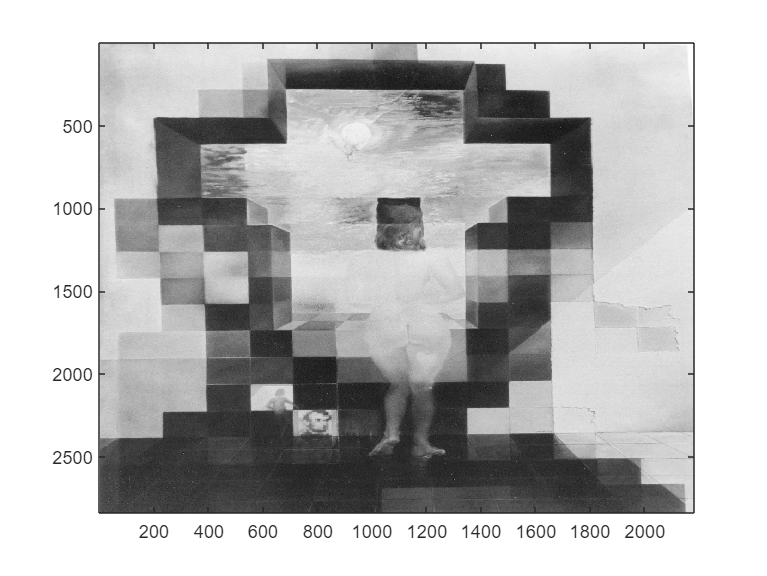

gala = double(rgb2gray(imread("gala-desnuda-mirando.jpg")));
[h,w] = size(gala);
imagesc(gala)
colormap('gray')

% Dimensiones
cm = 1e-2;
mm = 1e-3;
um = 1e-6;
nm = 1e-9;

lambda = 630*nm;

z =93;

% Metricas Ojo humano

diametroPupila = 4*mm; % En promedio

distanciaFovea = 2.5*cm; % Diametro promedio del ojo

% Magnificación de la imagen
M = (distanciaFovea/z) 

M = 2.6882e-04

% dimensiones de Gala en la retina
alto = (M)*4.2;
ancho = (M)*3.18;

dx = (ancho/w);
dy = (alto/h);

% Criterio de rayleigh
rayleigh = 1.22*(lambda/diametroPupila);
deltaDistanciaR = z*2*tan(rayleigh/2)

deltaDistanciaR = 0.0179

% Pupila y recorte de frecuencias 
frecuenciaDeCorte = (diametroPupila/2)/(lambda*z); % lambda*z son las dimensiones de pixel en el plano escalado de la pupila

deltaDistancia = 1/(frecuenciaDeCorte) % Minima distancia reconocible en metros

deltaDistancia = 0.0293

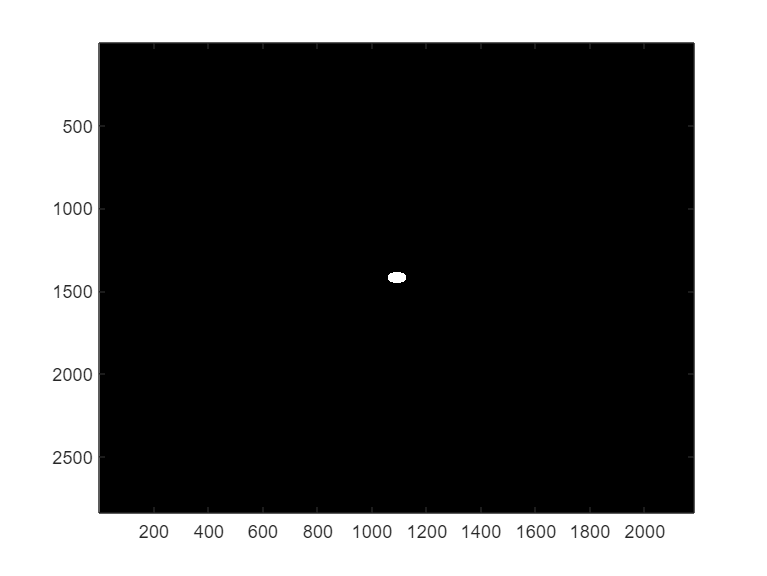

pupila = filtroCircular([w/2 round(h/2)],frecuenciaDeCorte,[h w]);
%ftpupila = fftshift(fft2(pupila));
imagesc(pupila);

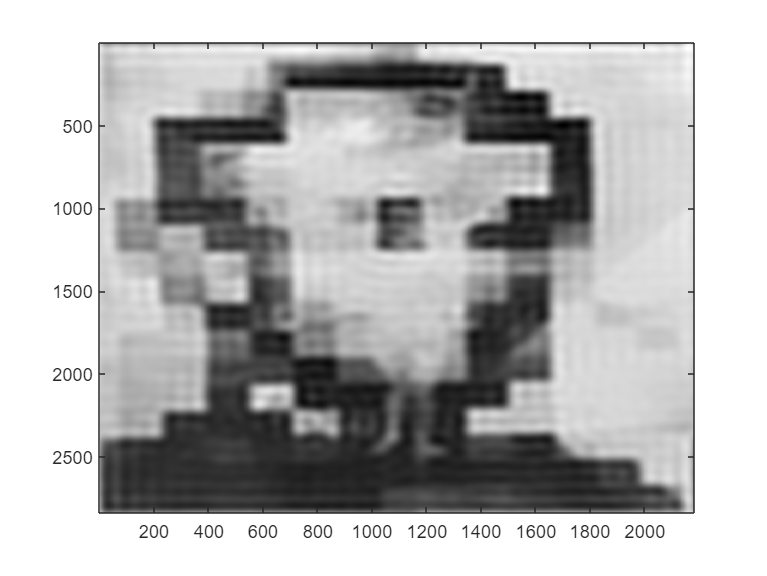

% Propaganción del sistema lineal 
campoSalida =(ifft2(pupila.*(fftshift(fft2(gala)))));
imagesc(abs(campoSalida))

% Prueba con dos puntos
sep = 20;
distSep = sep*0.0015

distSep = 0.0300

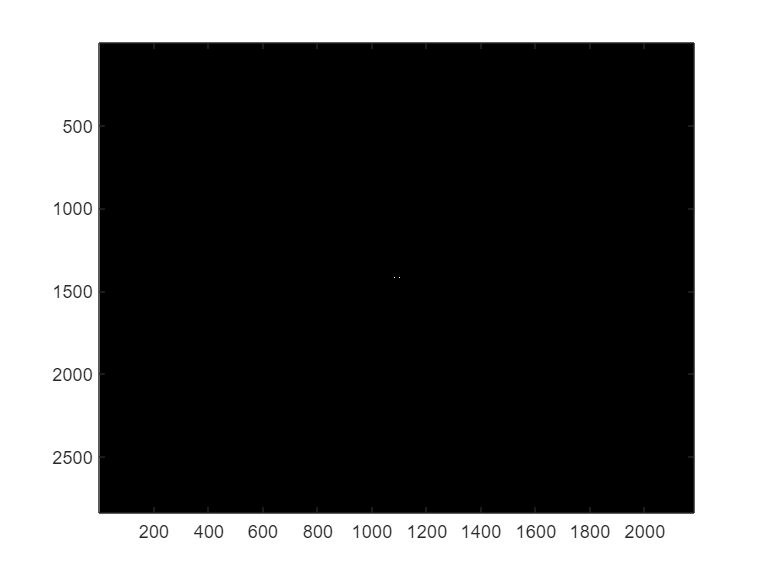


prueba = filtroCircular([(w/2)-round(sep/2) round(h/2); (w/2)+round(sep/2) round(h/2); ],[1 1],[h w]);
imagesc(prueba)

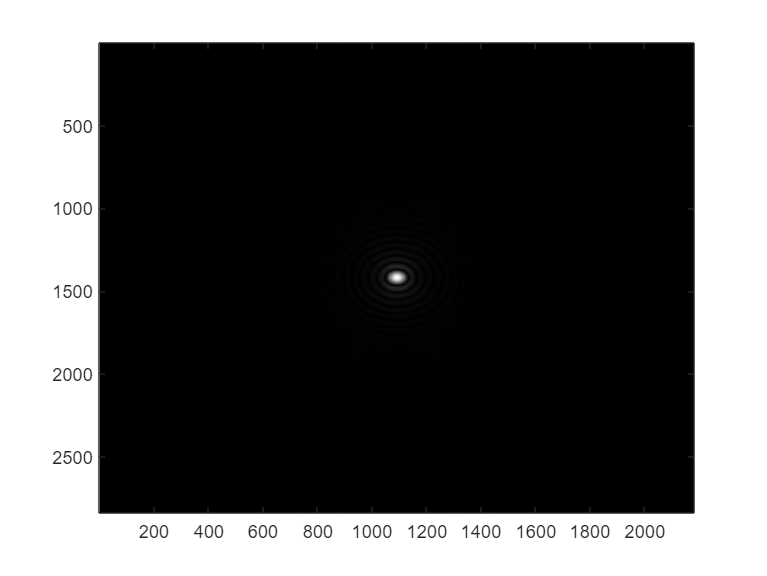

campoSalidaPrueba =(ifft2(pupila.*(fftshift(fft2(prueba)))));

imagesc((abs(campoSalidaPrueba)))